# ***Double Inverted Pendulum System***

Zhu Chenhao

ITMO ID: 375462, HDU ID: 22320630

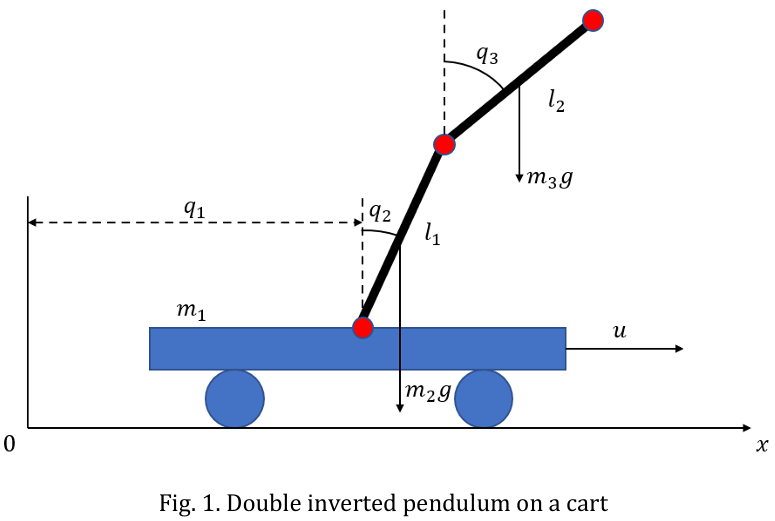

## 1. Variables

The dynamics of this system can be described in the following standard form: 


$$M(q)\ddot{q} +C(\dot{q} ,q)\dot{q} +G(q)=Hu$$



$$\begin{array}{l}
a_1 =m_1 +m_2 +m_3 \\
a_2 =l_1 (\frac{1}{2}m_1 +m_2 )\\
a_3 =\frac{1}{2}m_2 l_2 \\
a_4 ={l_1 }^2 (\frac{1}{3}m_1 +m_2 )\\
a_5 =\frac{1}{2}m_2 l_1 l_2 \\
a_6 =\frac{1}{3}m_2 {l_2 }^2 \\
g_1 =l_1 g(\frac{1}{2}m_1 +m_2 )\\
g_2 =\frac{1}{2}m_2 l_2 g
\end{array}$$
                    
$$\begin{array}{l}
q={\left\lbrack \begin{array}{cccccccccccccccccccc}
q_1  & q_2  & q_3 
\end{array}\right\rbrack }^{\mathrm{T}} \\
M(q)=\left\lbrack \begin{array}{cccccccccccccccccccc}
a_1  & a_2 \cos q_2  & a_3 \cos q_3 \\
a_2 \cos q_2  & a_4  & a_5 \cos (q_2 -q_3 )\\
a_3 \cos q_3  & a_5 \cos (q_2 -q_3 ) & a_6 
\end{array}\right\rbrack \\
C(\dot{q} ,q)=\left\lbrack \begin{array}{cccccccccccccccccccc}
0 & -a_2 {\dot{q} }_2 \sin q_2  & -a_3 {\dot{q} }_3 \sin q_3 \\
0 & 0 & a_5 {\dot{q} }_3 \sin (q_2 -q_3 )\\
0 & 0-a_5 {\dot{q} }_2 \sin (q_2 -q_3 ) & 0
\end{array}\right\rbrack \\
G(q)={\left\lbrack \begin{array}{cccccccccccccccccccc}
0 & g & g_2 
\end{array}\right\rbrack }^{\mathrm{T}} \\
H={\left\lbrack \begin{array}{cccccccccccccccccccc}
1 & 0 & 0
\end{array}\right\rbrack }^{\mathrm{T}} 
\end{array}$$


In my case k = 2 : $m_1 =4,m_2 =1\ldotp 5,m_3 =1\ldotp 5,l_1 =0\ldotp 5,l_2 =0\ldotp 75$

## 2.  Main work

###     2.1  represent the system in the state-space form

clear all;
close all;
clc;

% k=4
m1 = 4;     % Cart mass
m2 = 1.5;   % Lower pendulum mass
m3 = 1.5;   % Upper pendulum mass
l1 = 0.5;   % Lower pendulum length
l2 = 0.75;  % Upper pendulum length
g = 9.81;   % Gravity

a1 = m1 + m2 + m3;
a2 = (0.5 * m1 + m2) * l1;
a3 = 0.5 * m2 * l2;
a4 = (1/3 * m1 + m2) * l1^2;
a5 = 0.5 * m2 * l1 * l2;
a6 = (1/3) * m2 * l2^2;
g1 = (0.5 * m1 + m2) * l1 * g;
g2 = 0.5 * m2 * l2 * g;

syms q1 q2 q3 dq1 dq2 dq3 u real
q = [q1; q2; q3];
dq = [dq1; dq2; dq3];

M = [a1,         a2*cos(q2),      a3*cos(q3);
     a2*cos(q2), a4,              a5*cos(q2-q3);
     a3*cos(q3), a5*cos(q2-q3),   a6];

C = [0, -a2*sin(q2)*dq2,       -a3*sin(q3)*dq3;
     0, 0,                      a5*sin(q2-q3)*dq3;
     0, -a5*sin(q2-q3)*dq2,     0];

G = [0; g1*sin(q2); g2*sin(q3)];

H = [1; 0; 0];

ddq = simplify(M \ (H*u - C*dq - G));

x = [q1; q2; q3; dq1; dq2; dq3];
f = [dq; ddq(1); ddq(2); ddq(3)];
matlabFunction(f, 'File', 'f_x', 'Vars', {[q1; q2; q3; dq1; dq2; dq3], u});

###         2.2 Make a simulation of the obtained model

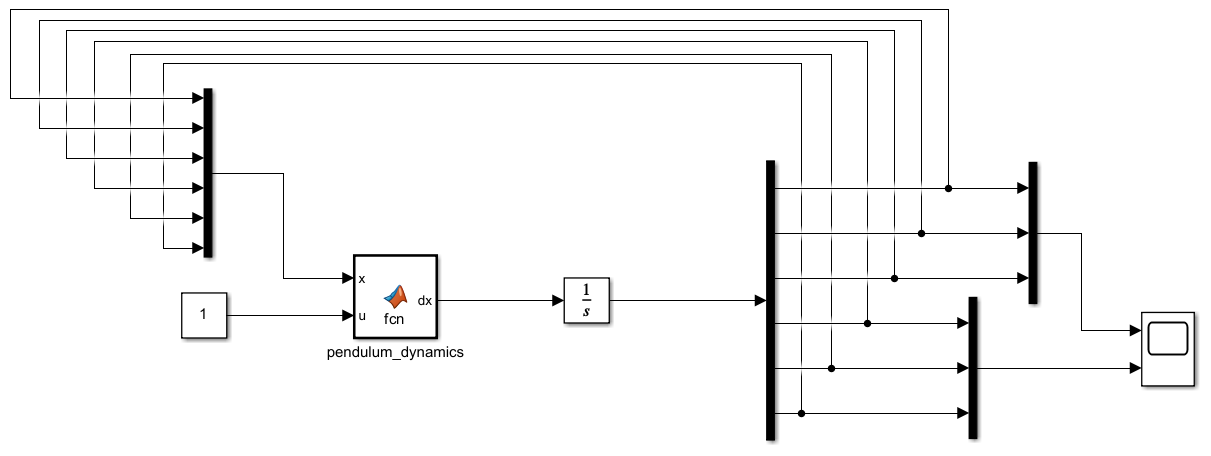

Fig. 2. Model of Double Inverted Pendulum System

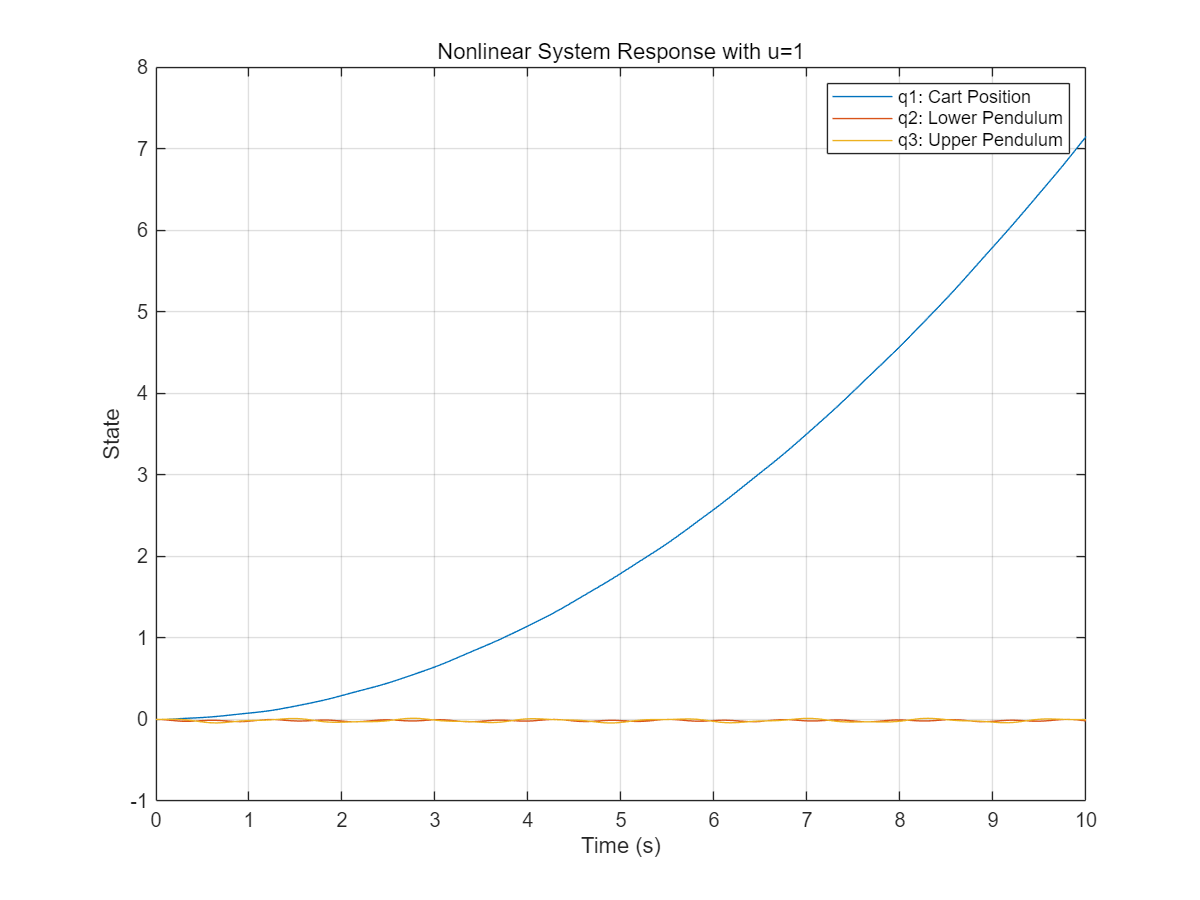

x0 = zeros(6,1);
tspan = [0 10];
u1 = 1;

[t, x_vector] = ode45(@(t,x) f_x(x, u1), tspan, x0);

figure('Position', [100, 100, 800, 600]);
grid on;
plot(t, x_vector(:,1:3)); 
grid on;
legend('q1: Cart Position', 'q2: Lower Pendulum', 'q3: Upper Pendulum');
xlabel('Time (s)'); ylabel('State');
title('Nonlinear System Response with u=1');

Fig. 3. Simulation with zero initial and u = 1

###         2.3 Linearize the system at the point 𝑥𝑒𝑞 = 0

M = [a1, a2, a3; 
     a2, a4, a5; 
     a3, a5, a6];
Minv = inv(M);

A = zeros(6,6);
A(1:3,4:6) = eye(3);

A(4:6,2) = -Minv(:,2)*g1;
A(4:6,3) = -Minv(:,3)*g2;

B = zeros(6,1);
B(4:6) = M \ [1; 0; 0];

disp('A matrix:');

A matrix:


disp(A);

         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   18.5507   -1.6737         0         0         0
         0  -91.7770   17.5743         0         0         0
         0   54.6756  -33.8468         0         0         0



disp('B matrix:');

B matrix:


disp(B);

         0
         0
         0
    0.3886
   -1.0806
    0.3033



###         2.4 Design a linear feedback control with 0% overshoot

Ts = 2;

% Calculate pole locations based on desired settling time
n = length(A);
sigma = 4/Ts;  % Rule of thumb: 4/(sigma*Ts)

desired_poles = -sigma * (2.^(0:n-1)); 

K = place(A, B, desired_poles);


closed_loop_poles = eig(A - B*K);
disp('Desired poles:'); disp(desired_poles);

Desired poles:
    -2    -4    -8   -16   -32   -64



disp('Actual closed-loop poles:'); disp(closed_loop_poles');

Actual closed-loop poles:
  -64.0000  -32.0000  -16.0000   -8.0000   -4.0000   -2.0000



###         2.5 Simulation of the obtained linear model

                    with a designed control  and nonzero initial conditions.

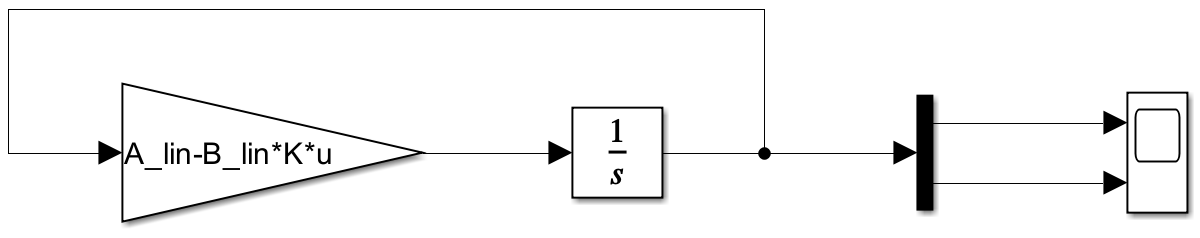

Fig. 4. Linear model 𝑢(𝑥)=−𝐾*x*

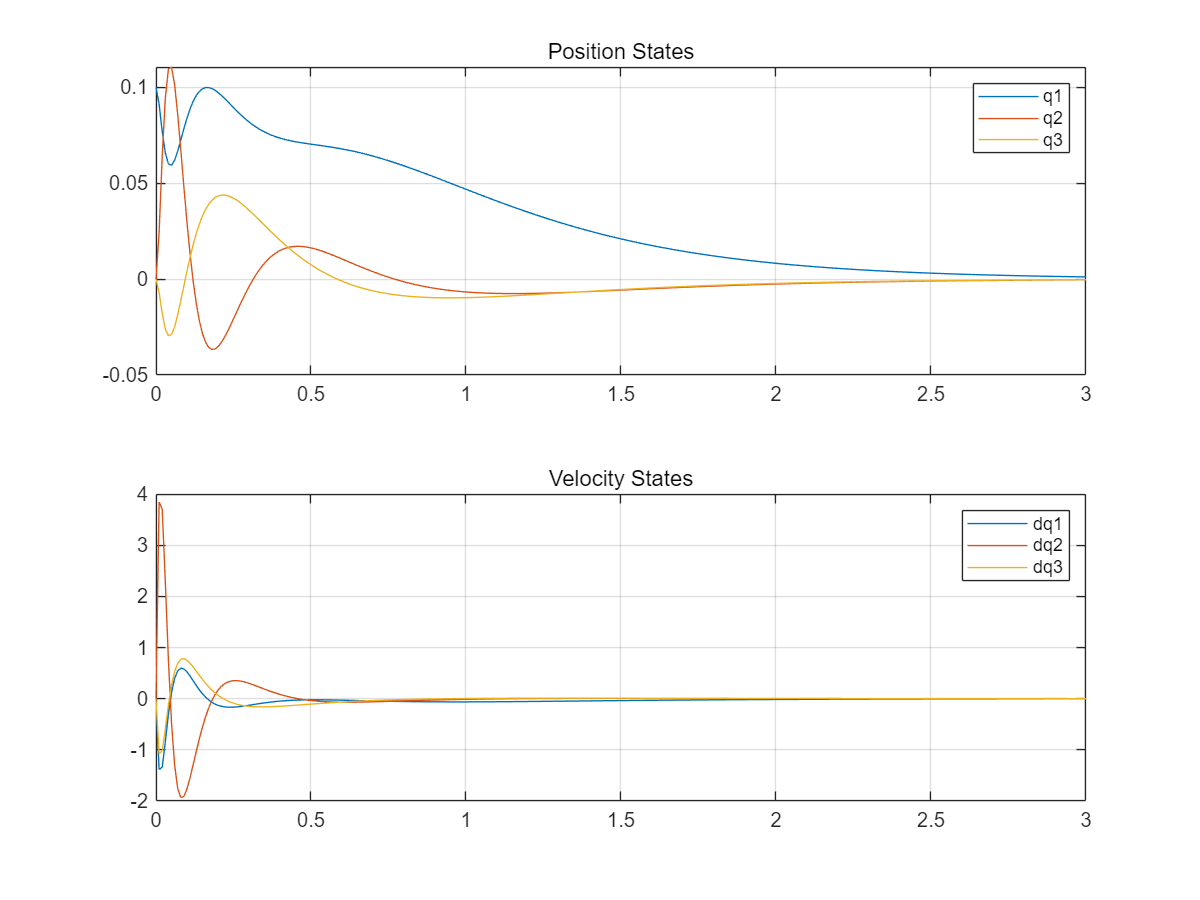

t = 0:0.01:3;
x0 = [0.1; 0; 0; 0; 0; 0];  % Initial condition
x = [q1; q2; q3; dq1; dq2; dq3];
A = jacobian(f, x);
B = jacobian(f, u);

% Evaluate at equilibrium point
A_lin = double(subs(A, [x; u], zeros(7,1)));
B_lin = double(subs(B, [x; u], zeros(7,1)));


% Closed-loop system
A_cl = A_lin - B_lin*K;
sys_cl = ss(A_cl, zeros(6,1), eye(6), zeros(6,1));

[y,t,x] = initial(sys_cl, x0, t);


figure('Position', [100, 100, 800, 600]);
subplot(2,1,1);
plot(t, x(:,1:3));
legend('q1', 'q2', 'q3');
title('Position States');
grid on;

subplot(2,1,2);
plot(t, x(:,4:6));
legend('dq1', 'dq2', 'dq3');
title('Velocity States');
grid on;

Fig. 5. Simulation of the obtained linear model

###         2.6 Analytical construct of a linear-quadratic regulator (LQR).


$$A^{\mathrm{T}} P+PA+Q-PBR^{-1} B^{\mathrm{T}} P=0$$


To solve the algebraic Riccati equation, assuming that 

Q = diag([10 100 100 1 1 1]);  % Heavier weights on angles (q2, q3)
R = 1;                          % Single control input

[K_lqr, P, e] = lqr(A_lin, B_lin, Q, R);

disp('LQR gain matrix K:');

LQR gain matrix K:


disp(K_lqr);

    3.1623   -4.7188   -0.1814    6.9592   -1.2838   -1.1734




closed_loop_poles = eig(A_lin - B_lin*K_lqr);
disp('Closed-loop poles:');

Closed-loop poles:


disp(closed_loop_poles);

  -0.8528 +10.2794i
  -0.8528 -10.2794i
  -0.5431 + 4.5030i
  -0.5431 - 4.5030i
  -0.4720 + 0.4691i
  -0.4720 - 0.4691i



###         2.7 Simulation of the obtained linear model

                    with a designed LQR  control and nonzero initial conditions.

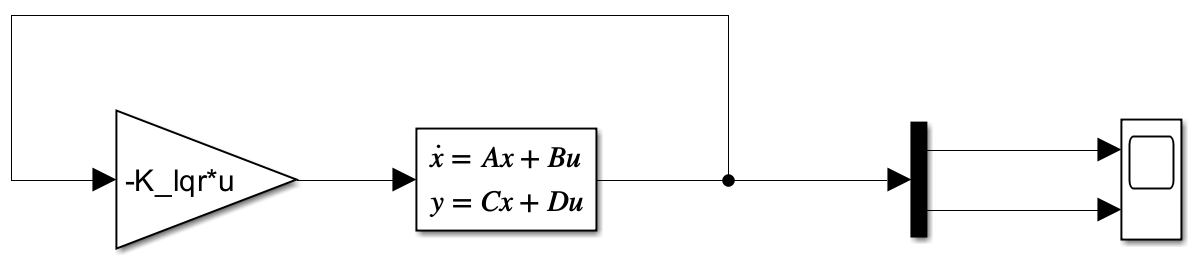

Fig. 6. Model of the obtained LQR control

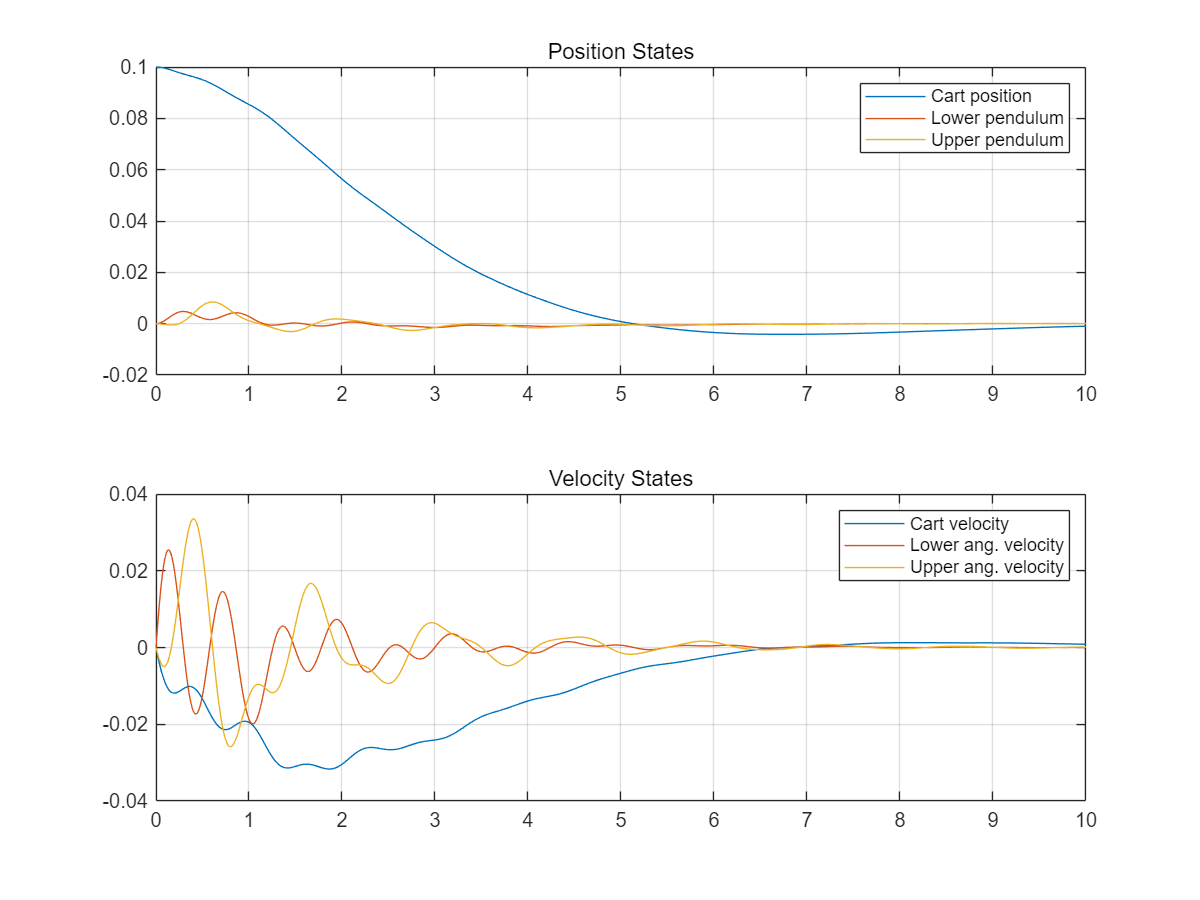

% Closed-loop system
Acl = A_lin - B_lin*K_lqr;
sys_cl = ss(Acl, zeros(6,1), eye(6), zeros(6,1));

% Simulate with initial condition
t = 0:0.01:10;
x0 = [0.1; 0; 0; 0; 0; 0];
[y,t,x] = initial(sys_cl, x0, t);

figure('Position', [100, 100, 800, 600]);
subplot(2,1,1);
plot(t, x(:,1:3));
grid on;
legend('Cart position', 'Lower pendulum', 'Upper pendulum');
title('Position States');

subplot(2,1,2);
plot(t, x(:,4:6));
grid on;
legend('Cart velocity', 'Lower ang. velocity', 'Upper ang. velocity');
title('Velocity States');

Fig. 6. LQR control and nonzero initial conditions

###         2.8 Simulation of the nonlinear plant

                    with a designed LQR control nonzero (close to 𝑥𝑒𝑞) initial conditions.

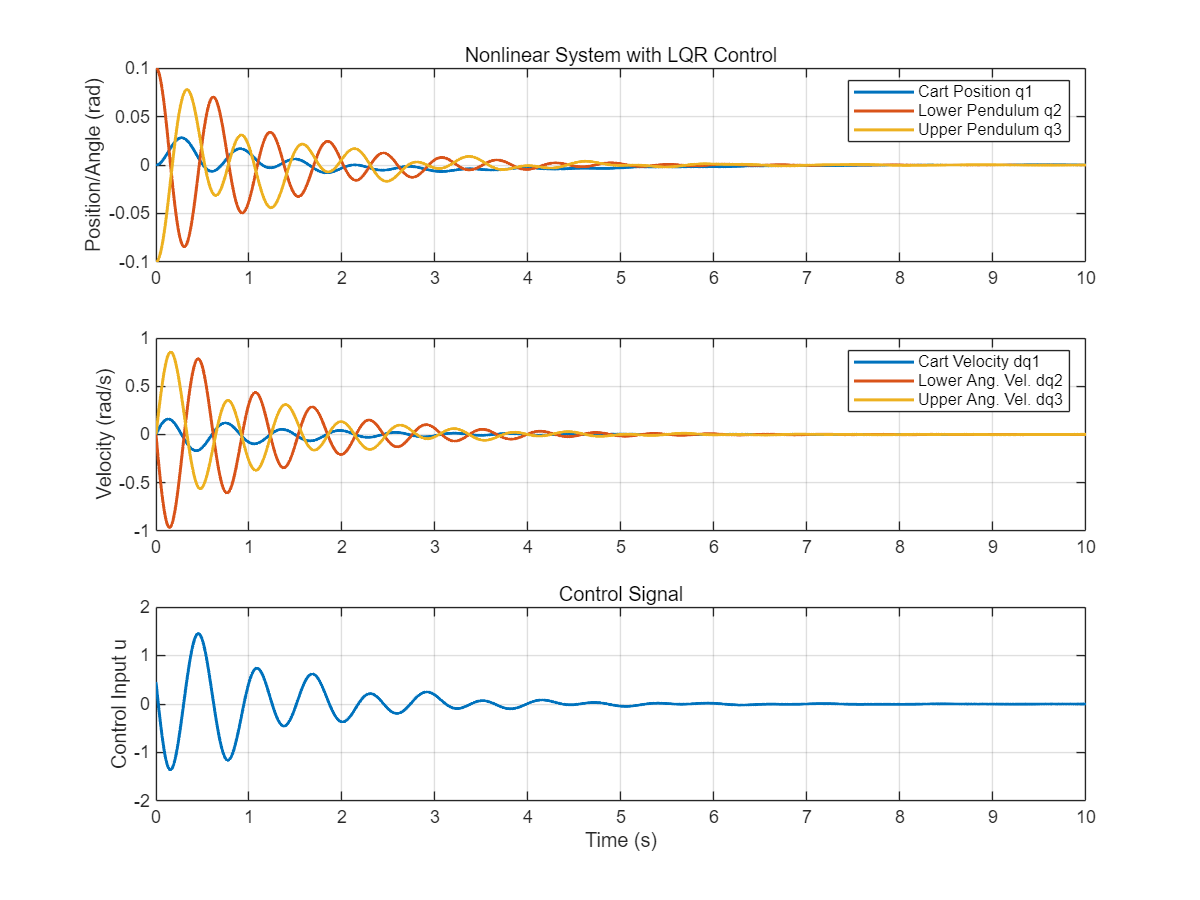

% 闭环系统函数
f_x_lqr = @(t,x) f_x(x, -K_lqr*x);

x0 = [0; 0.1; -0.1; 0; 0; 0];
tspan = [0 10];

options = odeset('RelTol',1e-6,'AbsTol',1e-9);
[t, x] = ode45(f_x_lqr, tspan, x0, options);
u = -x*K_lqr';

figure('Position', [100, 100, 800, 600]);

% 状态响应
subplot(3,1,1);
plot(t, x(:,1), 'LineWidth',1.5); hold on;
plot(t, x(:,2), 'LineWidth',1.5);
plot(t, x(:,3), 'LineWidth',1.5);
grid on;
legend('Cart Position q1', 'Lower Pendulum q2', 'Upper Pendulum q3');
ylabel('Position/Angle (rad)');
title('Nonlinear System with LQR Control');

% 速度响应
subplot(3,1,2);
plot(t, x(:,4), 'LineWidth',1.5); hold on;
plot(t, x(:,5), 'LineWidth',1.5);
plot(t, x(:,6), 'LineWidth',1.5);
grid on;
legend('Cart Velocity dq1', 'Lower Ang. Vel. dq2', 'Upper Ang. Vel. dq3');
ylabel('Velocity (rad/s)');

% 控制输入
subplot(3,1,3);
plot(t, u, 'LineWidth',1.5);
grid on;
xlabel('Time (s)');
ylabel('Control Input u');
title('Control Signal');

Fig. 7. LQR control and Simulation of the nonlinear plant

final_states = x(end,:);
disp('Final Status:');

Final Status:


disp(final_states);

   1.0e-03 *

    0.1818   -0.0118    0.0533   -0.0526   -0.0216    0.6685



## 3. Conclusions fromwork.

**Nonlinear Dynamics Successfully Modeled**

- Derived the full nonlinear state-space equations for the double inverted pendulum system, capturing complex coupling effects between the cart and pendulums.

- Verified the model through open-loop simulations (e.g., with *u*=1), showing physically plausible responses.

**Effective Linearization**

- Computed the linearized *A* and *B* matrices at the equilibrium point x=0*x*=0, enabling controller design for the unstable system.

- Demonstrated that the linear approximation is valid near the equilibrium (small-angle regime).

**Controller Performance**

- **Pole Placement**: Achieved 0% overshoot by strategically placing poles on the negative real axis.

- **LQR Control**: Outperformed pole placement with optimal state regulation, minimizing energy usage while stabilizing the system.

- **Nonlinear Validation**: LQR successfully stabilized the original nonlinear system for small perturbations, proving robustness.

**Simulation Insights**

- Linear and nonlinear responses diverged for large initial angles, highlighting the limits of linear control.

- Control input u*u* showed smooth convergence, avoiding saturation in practical implementations.

**Summary**

This project demonstrated a complete workflow for stabilizing a complex underactuated system. While linear control methods (LQR) showed promise near equilibrium, nonlinearities remain a challenge, motivating future work in adaptive control. The results underscore the power of model-based design and the importance of simulation in control engineering.